#  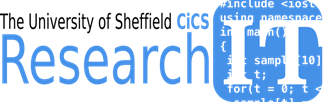                                      

# **Development, Debugging and Improving Performance **

# Overview

- matlab workbench

- help and matlab central

- working with vectors and matrices

- programming structures repetition and condition checking

- data types e.g. cell arrays, structures and handles

- functions and handles

- simple plotting

# Outline

- Code Analyzer

- Debugging

- Profiling and Timing

- Vectorisation

- Memory Management and Preallocation

- Algorithm Devlopment

Provide the tools to develop and maintain high quality software for your research. Properly documented to enable researchers to repeat and reuse your research.

The Matlab workbench and editor already provide many features to make programming much easier, just check the code fragment below. Copy and paste this fragment as a script in the matlab editor.

Observe how the matlab editor highlights warnings and errors on the right hand bar clicking on the individual items shows the warning/error and provides suggestions.

%% Simple example to show features
%Sample fragment to high light features of the workbench

a=1  %unused variable

a = 1


b=[1 2; 3 4]

b =      1     2
     3     4



c=[1  4]

c =      1     4



%FIXME
x=b*c


x =      1     8
     3    16



%% Another code section
%TODO
%add more code and doo something useful
y=b*b;

## Directory Reports.

Directory reports may be  used as a first step to obtain an overview of particular aspects of  files in a given directory (folder). Directory reports are available  from a drop-down list in the Current Folder Browser menu. Note that  these reports are specific to a given directory.

As a first step,  we can produce a Code Analyzer Report listing all Code Analyzer warnings for each file in the current folder. This will help us to fix  syntactical and other errors present in the current code.

Recommended activity: run a Code Analyzer Report to generate a summary of all Code Analyzer warnings and errors.

## Analyzing Code in the Editor.

The MATLAB  Editor has various integrated tools intended for code debugging. The  status box in the upper right-hand corner provides an indication of the  current status of the code. Green means that there are no detectable  errors in the code; orange means that there is potential for unexpected  results or poor performance, and red means that there are errors which  currently will prevent the code from running.

A summary of the  code issues can be obtained from the Code Analyzer Report as described  above. This analysis can also be done programmatically using the  CHECKCODE function:

addpath('../matlab_examples/casestudies/health/');
checkcode('findBestPredictors') %probably need to execute this from matlab workbench!

L 85 (C 33-40): The function 'getPairs' might be unused.
L 94 (C 9-11): FOR might not be aligned with its matching END (line 98).
L 95 (C 13-20): The variable 'varPairs' appears to change size on every loop iteration. Consider preallocating for speed.
L 96 (C 13-20): The variable 'varPairs' appears to change size on every loop iteration. Consider preallocating for speed.


# Using the Debugger

eaxample 

In the examples directory under the ***numericalanalysis/root_bisection***folder you will find a MATLAB script named **plotroot**. 

- Make sure to make directory named ***numericalanalysis/root_bisection ***your “Current Directory” via the “***Current Folder***” window or alternatively add this folder to the MATLAB Path via *the context-menu* of the folder named root in the *current-folder window*

# Using the Profiler

•Type profile viewer to start the profiler up and

•In the run this code field enter the name of your script file, or keep that field clear and just click on Start profiling followed by running your task as usual from the Matlab Command Window and when finish click on the stop profiling icon. 

•Clicking on the profiling summary icon will display a profile summary which can be expanded by clicking on the routine names on the list. 

**Measuring Performance: Stopwatch Timer**

•Start the timer

–tic

•Stop the timer

–toc

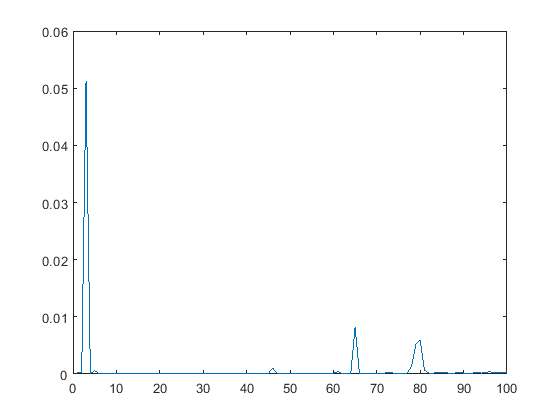

t = zeros(1,100);
for n = 1:100
    A = rand(n,n);
    b = rand(n,1);
    tic;
    x = A\b;
    t(n) = toc;
end
plot(t)

# Datatypes and Memory

In order to improve the memory usage and the performance of the MATLAB code, it is important to understand the memory requirements of the MATLAB datatypes. Judiciously choosing the datatype to store your data can increase the efficiency of your code.

You can determine the memory used by a variable by choosing to display the 'Bytes' column in MATLAB workspace. 

- The amount of memory required by a datatype increases with the increase in the range or the precision of the values that the datatype can express.

- Container variables (tables, cell arrays, and structure arrays) require overhead in addition to the data they store. This additional memory is used to store information about the contents of the variable. The amount of the overhead depends on the size of the variable.

## Special Variable Types

MATLAB has datatypes that are designed to be used with data having specific characteristics. These datatypes can significantly reduce the memory consumption.

Categorical arrays can be used to store a list of text labels or strings containing many repeated entries. Instead of storing each item in the list separately, a categorical array stores only the unique entries and creates references to these entries to represent the elements in the list. The memory savings are large when the list contains many repeated entries.

## Memory Anatomy.

On a Windows system, the  MEMORY command can be used to obtain available memory information.  Calling the MEMORY function with two outputs produces two structures  which contain user and system information, respectively.

[user, sys] = memory;
disp(user)

    MaxPossibleArrayBytes: 9.9957e+09
    MemAvailableAllArrays: 9.9957e+09
            MemUsedMATLAB: 1.4427e+09



disp(sys)

    VirtualAddressSpace: [1×1 struct]
           SystemMemory: [1×1 struct]
         PhysicalMemory: [1×1 struct]



**Total System Memory** (`sys.SystemMemory.Available`): Physical RAM available + Page File (or swap) available. It depends on the amount of RAM (fast, but expensive) and swap disk (cheap, but slow). To monitor system memory, you can also use the Windows Task Manager.

**MATLAB Process Virtual Memory** (`sys.VirtualAddressSpace`): Total and available memory associated with the whole MATLAB process. It is limited by processor architecture and operating system.

**MATLAB Workspace** (`user.MemAvailableAllArrays`) **and Largest block** (`user.MaxPossibleArrayBytes`): The effective workspace available for data is the MATLAB process virtual address space minus system DLLs, Java™ (JVM), MATLAB.exe and DLLs. The largest block (for numerical arrays) is affected by fragmentation, third-party DLLs , and other running processes. You can limit the size of the largest array that MATLAB can create. To set the limit, go to: MATLAB Preferences -> Workspace -> MATLAB array size limit.

## Preallocation of Memory.

When your code runs slower than expected, one of the things you can look at is how the variables are created and modified as the code runs.

MATLAB allows  variables to be resized dynamically, for example, during the individual  iterations of a loop. This is convenient, but in some cases can lead to  poor performance. 

- Preallocating memory in advance is the recommended  approach. 

- For numeric arrays, preallocation can be done using the  zeros/ones/NaN function.  

- It is important to preallocate for  the correct data type. All numeric data types are supported by zeros and ones; NaN may initialise double or single values. 

- Cells and structures  may be preallocated using the cell, struct and repmat functions.

clear all
x = zeros(1,50000);
whos

  Name      Size                Bytes  Class     Attributes

  x         1x50000            400000  double              



%You can create an array having other datatypes by specifying an additional input.	
x = zeros(1,50000,'single');
y = zeros(1,50000,'int16');
whos

  Name      Size                Bytes  Class     Attributes

  x         1x50000            200000  single              
  y         1x50000            100000  int16               



%Another way to preallocate an array is to assign a value to the last element of the array.	
x(8) = 3; %for this example check the workspace
whos

  Name      Size                Bytes  Class     Attributes

  x         1x50000            200000  single              
  y         1x50000            100000  int16               



- To preallocate a cell array using the function `cell`.

- To preallocate a structure array, start by defining the last element of the array. MATLAB will automatically replicate the field names to all of the preceding elements in the array.

C = cell(1,4); 
S(5) = struct('field1',6,'field2',7)

S = 1×5 struct array with fields:
    field1
    field2


whos

  Name      Size                Bytes  Class     Attributes

  C         1x4                    32  cell                
  S         1x5                   432  struct              
  x         1x50000            200000  single              
  y         1x50000            100000  int16               



Study the function makeA.m in the folder course_examples/usingmatlab/vectorize

Run the function by enterting the following command in the command window. Observe the elapsed time.

`tic``;` `A` `=` `makeA``(``5000``,``100``)``;` `toc` 

Write code to preallocate the array `A` inside the function and run the function again by enterting the above command in the command window. 

Observe the effect of preallocation on the elapsed time. 

addpath('../matlab_examples/usingmatlab/vectorize/');
edit('makeA.m');
tic; A = makeA(5000,100); toc

Elapsed time is 0.707021 seconds.


# Vectorisation

MATLAB is an array-based language, and as such all vector and matrix  operations are optimised for performance. Replacing sequences of scalar  operations performed in loops with smaller numbers of vector and matrix  operations is referred to as vectorisation. This process can lead to  more readable and efficient code.

Think of the best way of completing each of the following tasks in MATLAB:

- Add two vectors `x` and `y`.

- Find the square root of each of the elements of the vector `n`.

- Calculate the difference between the adjacent elements of the vector `x`.

Each of the above tasks can be performed using a `for` loop. However, MATLAB has many vectorized functions and operators which provide an alternative to the`for` loop and are often faster and more concise.

Other useful functions include `sum, diff, prod, gradient, del2`

•Some matlab routines are *.m files, others are compiled into matlab (built-in) and are much faster. Try to use built-ins where possible. Use type *functionname* to see if a function is a built-in. 

A subset of vectorized functions and operations is provided below. You should look for opportunities to vectorize your code and consult MATLAB documentation for possible solutions.

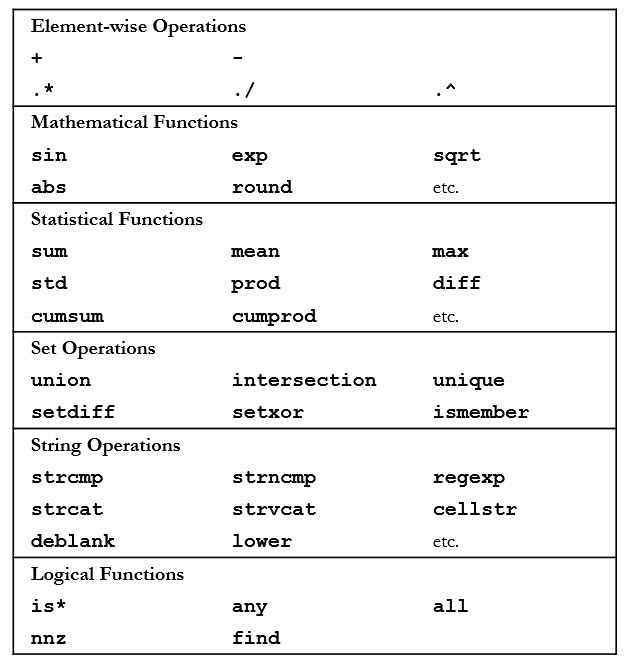

•Matlab scripts can be written using fortran/C-style "for" loops, but to make the most of matlab's abilities you should try whenever possible to treat matrices as a single entity rather than a bundle of elements.

•Vectorisation functions

–`arrayfun, strutfun, cellfun`

`–repmat`

`–cumsum`

–`bsxfun` (Binary Singleton eXpansion FUNction) 

tic
for i = 1:100 
	for j = 1:100 
		r(i,j) = sqrt(i^2+j^2); 
	end 
end
toc

Elapsed time is 0.046957 seconds.


vectorised this becomes

tic
[i,j]=meshgrid(1:100,1:100);
r = sqrt(i.^2+j.^2); 
toc

Elapsed time is 0.036442 seconds.


Note for small loops there is no discernable performance gain, for what size of loop do we gain benefit? Investigate and find out!

## Vectorisation: Example 2

tic
n=1000; x(1)=1; 
for j=1:n-1, 
	x(j+1) = x(j) + n - j; 
end 
toc

Elapsed time is 0.025192 seconds.


vectorised using the cumulative summation function `cumsum`

tic
n=1000; x(1)=1; 
j=1:n-1; 
x(j+1) = n - j; 
cumsum(x); 
toc

Elapsed time is 0.036498 seconds.


## The cellfun, strutfun and arrayfun

Apply function to each element of array or cellaray using `arrayfun` or `celfun `or` strutfun`

`[B1,...,Bn] = arrayfun(func,A1,...,An)`

`[A1, ...,An ]= cellfun(func,C1,...,Cn)`

tic
x=-pi:pi/1000:pi;
y=arrayfun(@sin,x);
toc

Elapsed time is 0.030858 seconds.


compare with for loop

tic
x=-pi:pi/1000:pi;
for i=1:numel(x)
    y(i)=sin(x(i));
end
toc

Elapsed time is 0.031836 seconds.


For in-buillt and functions we can easily write! 

tic
x=-pi:pi/1000:pi;
y=sin(x);
toc

Elapsed time is 0.029193 seconds.


Handling arrays of different sizes

clear all
[4;5;6] > [1 2 3; 4 5 6; 7 8 9] %note for later versions of matlab matrix will automatically be expanded to 

ans = 3×3 logical array
   1   1   1
   1   0   0
   0   0   0


                                %do the computation

%the following solution increases memory usage

reshape(repmat([4;5;6],3,1),3,3) > [1 2 3; 4 5 6; 7 8 9]

ans = 3×3 logical array
   1   1   1
   1   0   0
   0   0   0


`bsxfun` to perform operations on arrays having different dimensions. This MATLAB function applies the element-wise binary operation specified by the function handle fun to arrays A and B.

x = [4;5;6]

x =      4
     5
     6


y = [1 2 3; 4 5 6; 7 8 9];
bsxfun(@gt,x,y)

ans = 3×3 logical array
   1   1   1
   1   0   0
   0   0   0


Note above the handle to the 'greater than' function `gt`. Note that all MATLAB operators have equivalent function forms. For example, the `>` and `+` operators are equivalent to the `gt` and `plus` functions, respectively.

bsxfun does the following

- Replicate input arrays along singleton dimension until resulting dimensions match.

- Perform binary function on each element to produce output.

## Copy on write behaviour

When assigning one variable to another, MATLAB does not create a copy of that variable until it is necessary. Instead, it creates a reference. 

When you assign a copy of a large variable to another variable, how is the 'available memory' affected? Such situations often arise when passing inputs to a function.

MATLAB does maintain the local copy of the variable inside the function. However, the copy is simply a reference to the variable which was passed as a function input. MATLAB breaks the reference, and creates an actual copy of that variable, only when code modifies one or more of the values.

This behavior, known as copy-on-write, or lazy-copying, ensures that no additional memory is assigned to an input variable until it is modified within the function.

clear all
A = rand(6e3);
m = memory;
disp('Memory available (GB):')

Memory available (GB):


disp(m.MemAvailableAllArrays/1073741824)

    9.0025



B = A;
% This is only a reference at the moment, so available memory should
% remain constant.
m = memory;
disp('Memory available (GB):')

Memory available (GB):


disp(m.MemAvailableAllArrays/1073741824)

    9.0126



B(1, 1) = 0;
% Now that we have made a change, copy-on-write should kick-in.
m = memory;
disp('Memory available (GB):')

Memory available (GB):


disp(m.MemAvailableAllArrays/1073741824)

    8.7332



## In-Place Optimisation.

An in-place optimisation conserves memory by using the same variable for an output argument as for an input argument. This is valid only when the input and output have the same size and type, and only within functions. When working on large data and memory is a concern, in-place optimisations could be used to attempt to conserve memory use. However, in some situations, it is not possible to have a true in-place optimisation, because some temporary storage is necessary to perform the operation.

When performing calculations on a variable having large size, you can improve memory usage if you avoid using temporary variables.

Consider the following code snippet.

`y` `=`` x.^2 ``+`` 1;`

If the variable `x` is not required in the program after the calculation is performed, you can avoid creating an additional variable `y` by assigning the result back to `x`. This approach saves memory as well as execution time for allocating new memory.

`x` `=`` x.^2 ``+`` 1;`

You can also benefit from the in-place optimization if you declare and call a function using the same variable to define the input and output arguments.

clear all
edit('inplace1.m')
edit('inplace2.m')
x1=rand(5000);
x1=inplace1(x1);
m = memory;
disp('Memory available (GB):')

Memory available (GB):


disp(m.MemAvailableAllArrays/1073741824)

    9.0830




clear all
x2=rand(5000);
x2=inplace2(x2);
m = memory;
disp('Memory available (GB):')

Memory available (GB):


disp(m.MemAvailableAllArrays/1073741824)

    9.1014



If `inplace1` or `inplace2` modifies the input variable and returns it in an appropriate way, the operation will be carried out without an additional copy in the MATLAB workspace.

This strategic technique is useful for large data sets, when a duplicate of the variable would immediately stop the execution by throwing an out-of-memory error.

## Nested Loops

MATLAB functions are typically used for organizing the code, avoiding replication, and hiding functionality.

- You can also use the functions for managing memory and interfaces. 

- write nested functions to effectively share large data between functions and conforming to a predetermined function signature while writing certain applications.

- Like a local function, a nested function is also used to organize several functions in a single function file and it often acts as a helper function to the primary function.

However, nested functions exihibit one additional feature: They allow functions in the file to share workspace variables. 

In the grossIncome example, below, the functions `convertToDollar` and convertToStirling share workspace variables with the `grossIncome` function and with each other.

Note that even while the shared data is accessible from anywhere within the file, it is hidden from the outside world.

## How to create a nested function?

To nest a function inside another function, the extents of the functions must be marked explicitly by using the keywords `function` and `end`.

edit('grossIncome.m')
grossIncome(50,100, 80)

ans = 380

In the example above if `dollarIncome,euroIncome, stirlingIncome`  are large, using a nested function is more efficient because it operates directly on the data of the parent function.

# More Performance More Data!

## Distributed Computing

•Coarse grained

–Multiple tasks

–High throughput computing

•Fine grained

–Distributed computing

–MPI programming distributed matrices

–GPU Arrays

## Acces to More Resources

•HPC

–[Sheffield Advanced Research Computer](https://www.sheffield.ac.uk/cics/research/hpc/intro)

•Benefits

–Access to data

–More compute resources

–Share applications with collaboration partners

## Make Matlab Use more Resources

•Compute Cluster e.g. Iceberg

•Uses a scheduler e.g. Sun Grid Engine

•Break a matlab job in to many independent tasks

–E.g. cycle of a for loop might run independently

•Array of matlab tasks running on compute cluster

•Can run 1000’s of tasks

•Good for 

–parametric sampling

–Genetic algorithms

–Model ensembles

**Submitting a matlab job to Sun Grid Engine ShARC**

•qsub mymatlabjob.sh

•Where mymatlabjob.sh is:

#!/bin/sh

#$ -cwd

#$ -l h_rt=hh:mm:ss

#$ -l rmem=12G 

module load apps/matlab/2017a

matlab -nojvm -nosplash -nodisplay < matlabscriptfile > outputfile

addpath('../matlab_examples/casestudies/beats_taskarray/')
edit('beats.m')
edit('beats.sh')

## Final Remarks

•Task arrays are a powerful method utilising large pools of compute resources e.g. clusters

•Mainly use batch submission mode not interactive use of matlab

•Parallel computing toolbox enables researchers to develop interactive matlab applications able to exploit a pool of compute resources

# A Case Study

## Linear Regression Models.

The main example in this chapter is developing an algorithm to perform data preprocessing,  fitting and visualisation. We will use a linear regression model with  variables chosen from the biomedical data discussed in the first chapter of the course. The examples are fairly simple, but if attendees are  unfamiliar with regression, the concepts can be explained in terms of  inputs and outputs. For example, we have an input variable (e.g. Age)  and we would like to model the dependency of an output variable (e.g.  PulsePressure) on the input. It's easier to gather the commands in these sections into a single script, which can then be run section by section and then eventually converted into a properly structured function by  the end of the chapter.

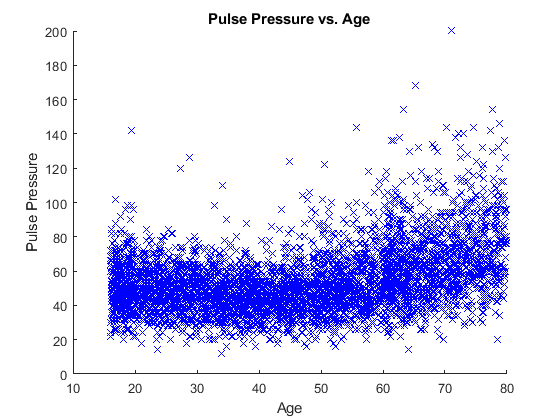

addpath('../matlab_examples/casestudies/health/')
% Visualise the dependency of pulse pressure on age.
load('S02_MedData.mat')
x = MedData.Age;
y = MedData.BPDiff;
figure
scatter(x, y, 'bx')
xlabel('Age')
ylabel('Pulse Pressure')
title('\bfPulse Pressure vs. Age')


% This dependency looks as if it could be modelled using a quadratic curve
% (i.e. using a model of the form PP ~ C0 + C1*Age + C2*Age.^2, where the
% coefficients C0, C1 and C2 are unknown and to be determined).

## Matrix Equations.

Formulating a linear  regression model leads to a system of linear equations A*x = b for the  unknown vector of coefficients x. The design matrix A comprises the  model terms, and the vector b is the data to be modelled (in this  example, the vector of pulse pressure observations). Note carefully that solving such linear systems is a matrix operation, and so any missing  values contained in the data must be dealt with in some way before  attempting to solve the system. (High-level functionality in Statistics  Toolbox can remove missing observations automatically before fitting,  but here we use a core MATLAB solution.)

% Set up the system of equations for fitting a model to the pulse pressure
% data.
missingIdx = isnan(x) | isnan(y);
xClean = x(~missingIdx);
yClean = y(~missingIdx);
designMat = [ones(size(xClean)), xClean, xClean.^2];


## Slash and Backslash.

The least-squares  solution of the system A*x = b in MATLAB is given by x = A\b. If the  system is formulated as x*A = b, then its solution is x = b/A.

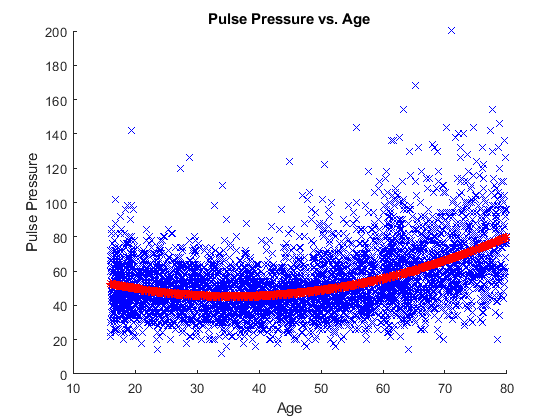

% Solve the linear system to find the best-fit coefficients for modelling
% pulse pressure as a quadratic function of age.
modelCoeffs = designMat\yClean;

% Compute the fitted model.
pulseModel = designMat*modelCoeffs;

% Visualise the results.
hold on
plot(xClean, pulseModel, 'r*')
hold off

## Matrix and Array Operators.

Note that in the  above computations we have used the operators * and \. A complete list  of matrix, array and logical operators is available by entering the  command >> doc ops.

doc ops
% It's useful to show this list at this point to point people in the right
% direction for discovering matrix and array operators.

## Generalising the Model.

We now have an  algorithm for fitting a one-dimensional quadratic model to our data. We  would like to generalise this to fit a two-dimensional quadratic surface to a single response variable given two input variables. For example,  we might be interested in predicting a person's weight given knowledge  of their height and waist measurements. We will follow similar steps to  preprocess and clean the data before fitting.

% Extract input variables.
x1 = MedData.Height;
x2 = MedData.Waist;

% Extract output variable.
y = MedData.Weight;

% Clean the data.
missingIdx = isnan(x1) | isnan(x2) | isnan(y);
x1Clean = x1(~missingIdx);
x2Clean = x2(~missingIdx);
yClean = y(~missingIdx);

% Formulate the system of linear equations.
designMat = [ones(size(x1Clean)), x1Clean, x2Clean, x1Clean.^2, ...
             x2Clean.^2, x1Clean.*x2Clean];

% Solve the system.
modelCoeffs = designMat\yClean;

## Function Handles.

Now that we have the second set of model coefficients for the 2D quadratic model, we would like to  visualise the fitted results. To do this, we need to substitute the  model coefficients into the model equation. One way to achieve this is  to use a function handle, which is a variable containing a reference to a function. Using a function handle reduces the problem of calling a  function to that of accessing a variable. The function handle contains  all information necessary to evaluate the function at given input  arguments. For further information on function handles, see MATLAB -> Language Fundamentals -> Data Types -> Function Handles.

modelFun = @(c, x1, x2) c(1) + c(2)*x1 + c(3)*x2 + c(4)*x1.^2 + ...
                        c(5)*x2.^2 + c(6)*x1.*x2;
% It's helpful to draw the analogy with the mathematical notation:
% f(c, x1, x2) = c(1) + c(2)*x1 + c(3)*x2 + c(4)*x1.^2 + ...
%                       c(5)*x2.^2 + c(6)*x1.*x2
% The only difference between the mathematical notation and the function
% handle definition is the "@" symbol, signifying to MATLAB that a function
% handle is being created.
% This function handle can now be evaluated at any point or any series of
% points, just like a normal mathematical function. For example:
disp(modelFun(modelCoeffs, 0, 0)) % Evaluates the model function at (0,0).

   11.6610



## Creating Equally-Spaced Vectors.

At this  point, we are ready to visualise our quadratic surface. In MATLAB,  surface plots can be created using a fairly straightforward step-by-step procedure. The first step of this process is to create equally-spaced  vectors of points of "x" and "y" data (the data forming the horizontal  plane). To achieve this, we could use either the colon operator (:) or  the LINSPACE function.

x1Vec = linspace(min(x1Clean), max(x1Clean));
x2Vec = linspace(min(x2Clean), max(x2Clean));
% Note that 100 points in the vector is the default. The number of points
% is optional and can be specified as the third input argument to LINSPACE.

## Making Grids.

The second step in the  procedure is to create matrices containing the coordinates of all grid  points in the lattice. This can be achieved using MESHGRID.

[X1Grid, X2Grid] = meshgrid(x1Vec, x2Vec);
% X1Grid contains all the "x" coordinates of all the lattice points.
% X2Grid contains all the "y" coordinates of all the lattice points.

% Now that we have all lattice points, our surface function can be
% evaluated over the lattice using the function handle defined above.
YGrid = modelFun(modelCoeffs, X1Grid, X2Grid);

## Surface Plots.

Finally, we can visualise the  surface. The basic function here is SURF, into which we provide the  three matrices of surface data (the two coordinate matrices and the  values of the surface function over the lattice).

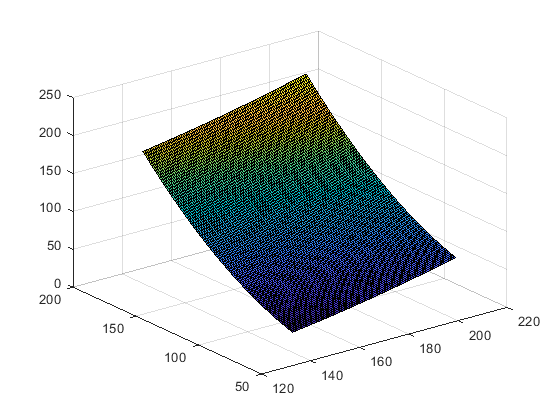

figure; surf(X1Grid, X2Grid, YGrid)

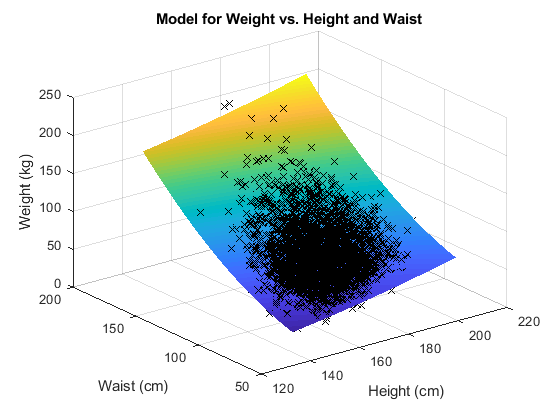

% We can customise this display by specifying name-value pairs.
surf(X1Grid, X2Grid, YGrid, 'FaceColor', 'interp', 'EdgeAlpha', 0)
% This removes gridlines and uses interpolated shading for the surface,
% instead of colouring each patch a uniform colour.

% View the original data.
hold on
plot3(x1Clean, x2Clean, yClean, 'kx')
xlabel('Height (cm)')
ylabel('Waist (cm)')
zlabel('Weight (kg)')
title('\bfModel for Weight vs. Height and Waist')


% Other 3D visualisation functions can be found in the Plot Gallery.

## Creating a Function.

At this point, we now  have a script which we can run to perform our data clean-up, model  fitting and visualisation. However, it is not straightforward to apply  the algorithms in our script to another set of data. The next step in  modularising our code is to create a function to automate the tasks or  subtasks represented in our current script. Functions are created in  text files with the .m extension, just like script files. However,  functions must begin with a function declaration of the form: function  [out1, out2, ...] = function_name(in1, in2, ...) The keyword "function"  must be the first non-comment code in the file. Syntax for calling  user-defined functions is identical to that used for calling existing  MATLAB functions.

% Recommended activity: create a new function "fitQuadModel" with the
% following declaration line:
% function [modelCoeffs, fh] = fitQuadModel(X, y, showplot)
%
% See the file F02_fitQuadModel_001.

## Workspaces.

Functions operate within their  own function workspace, which is separate from the base workspace  accessed at the prompt or from within scripts. If a function calls  another function, each maintains its own separate workspace. Once a  function has completed, its workspace is destroyed. Instructors may wish to demonstrate the concept of separate workspaces by setting  breakpoints and entering debug mode.

## Local Functions.

There may be times when we wish to outsource certain tasks in a function to  another function. For example, if we think about our algorithm at a  high-level, we are performing three distinct tasks: * we are cleaning up the data by removing NaNs; * we are performing the model fitting; * we  are visualising the results of the fitted model.

We are performing these three tasks on two distinct sets of data. One possibility for  structuring our main function is to have three local functions defined  inside, each of which represents one of the three tasks above. This  enables us to reuse the same function for multiple different sets of  data.